# **TD7**

clc;
clear;
close all;

Fonction de perte : Regression = mse ;classification = crossentropy

### **1/Chargment et préparation des données**

% Chargement du dataset
dataset = load('emnist-digits.mat');

% Préparation des données d'entraînement
Xtrain = dataset.dataset.train.images(1:5000, :)';
Xlabels = dataset.dataset.train.labels(1:5000, :);
Xtrain_images = reshape(Xtrain, 28, 28, 1, []);

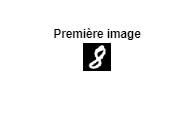

% Affichage d'une image avant reshape
figure;
imshow(reshape(Xtrain(:, 1), [28, 28]), []);
title('Première image');

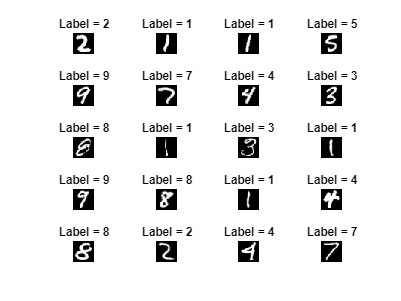


% Affichage aléatoire de 20 images
num_images = 20;
max_start = size(Xtrain, 2) - num_images;
r = randi(max_start, 1);

figure;
for j = 1:num_images
    img = reshape(Xtrain(:, r + j - 1), [28, 28]);
    subplot(5, 4, j);
    imshow(img, []);
    title(['Label = ', num2str(Xlabels(r + j - 1))]);
end

### **2/Encodage des labels d'entraînment**

% Encodage one-hot des labels d'entraînement
num_classes = 10;
one_hot_labels = zeros(num_classes, size(Xlabels, 1));
for i = 1:size(Xlabels, 1)
    one_hot_labels(Xlabels(i) + 1, i) = 1;
end

### **3/Entraînement des autoencodeur**

#### **a/ Autoencodeur 1:**

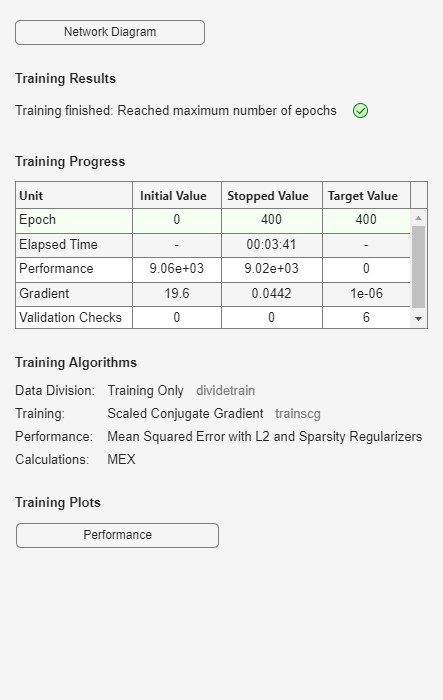


% Entraînement du premier autoencodeur
hiddenSize1 = 200;
autoenc1 = trainAutoencoder(Xtrain, hiddenSize1, ...
    'MaxEpochs', 400, ...
    'ScaleData', false, ...
    'L2WeightRegularization', 0.004, ...
    'SparsityRegularization', 4, ...
    'SparsityProportion', 0.15);

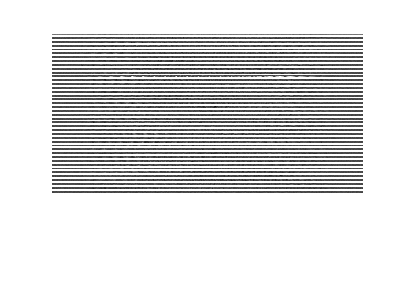


% Affichage des poids et de la structure
figure;
plotWeights(autoenc1);

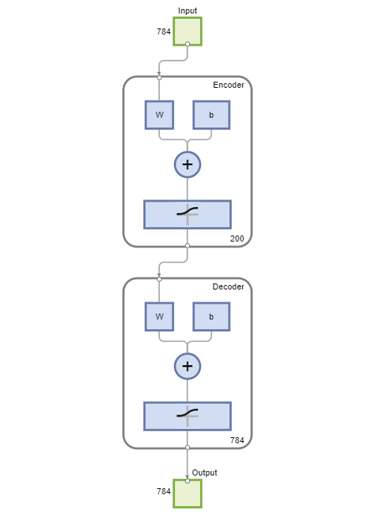

view(autoenc1);


% Extraction des caractéristiques du premier encodeur
features1 = encode(autoenc1, Xtrain);

#### **b/Autoencodeur 2:** 

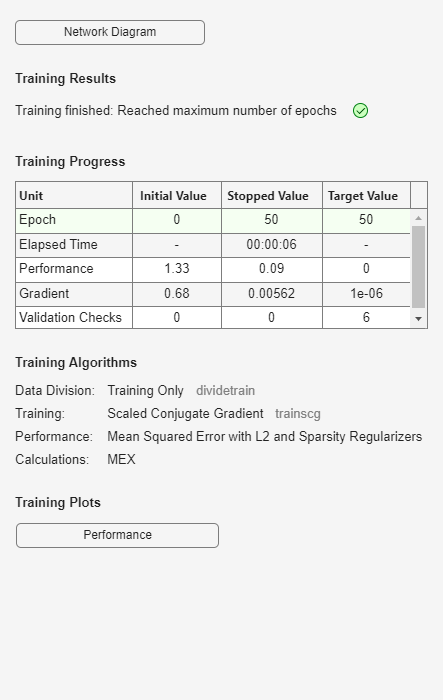

% Entraînement du second autoencodeur
hiddenSize2 = 100;
autoenc2 = trainAutoencoder(features1, hiddenSize2, ...
    'MaxEpochs', 50, ...
    'ScaleData', false, ...
    'L2WeightRegularization', 0.004, ...
    'SparsityRegularization', 4, ...
    'SparsityProportion', 0.15);

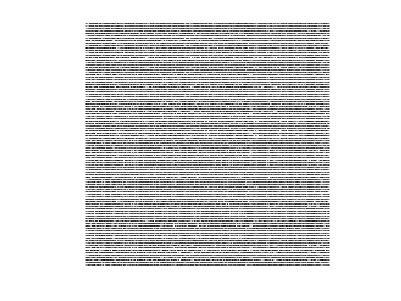


% Affichage des poids et de la structure
figure;
plotWeights(autoenc2);

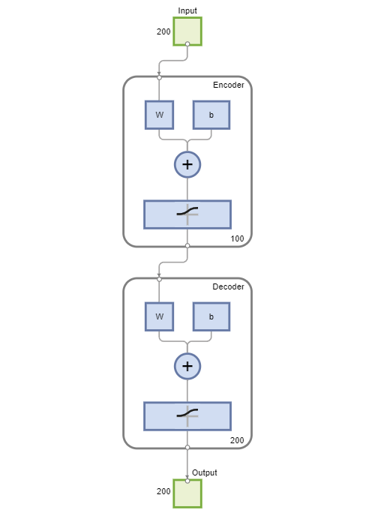

view(autoenc2);


% Extraction des caractéristiques du second encodeur
features2 = encode(autoenc2, features1);

### 4/Entraînement de la couche de classification avec patternet

% Création et entraînement du réseau de neurones de classification
patternnet_layer = patternnet(num_classes, 'trainscg', 'crossentropy');

D'après la documentation matlab :

La fonction **trainrp** est l'algorithme le plus rapide pour les problèmes de reconnaissance de formes. Cependant, elle ne donne pas de bons résultats pour les problèmes d'approximation de fonctions. De plus, ses performances diminuent à mesure que l'objectif d'erreur est réduit. Les exigences en mémoire pour cet algorithme sont relativement faibles par rapport aux autres algorithmes étudiés.

Les algorithmes de gradient conjugué, en particulier **trainscg**, offrent de bonnes performances sur une grande variété de problèmes, notamment pour les réseaux avec un grand nombre de poids. L'algorithme SCG est presque aussi rapide que l'algorithme LM pour les problèmes d'approximation de fonctions (et plus rapide pour les grands réseaux), et presque aussi rapide que **trainrp** pour les problèmes de reconnaissance de formes. De plus, ses performances ne se dégradent pas aussi rapidement que celles de **trainrp** lorsque l'erreur est réduite. Les algorithmes de gradient conjugué ont des exigences en mémoire relativement modestes.

Ici on utilise donc la fonction **trainsgc **pour l'entraînement car après quelques essais j'ai pu constatezr quelle donnait de meilleurs résultats que la fonction **trainrp **:

Et on utilise la fonction de perte 'crossentropy' qui calcule la perte d'entropie croisée entre les prédictions du réseau et les cibles binaires ou encodées en one-hot, pour les tâches de classification à étiquette unique ou à étiquettes multiples.

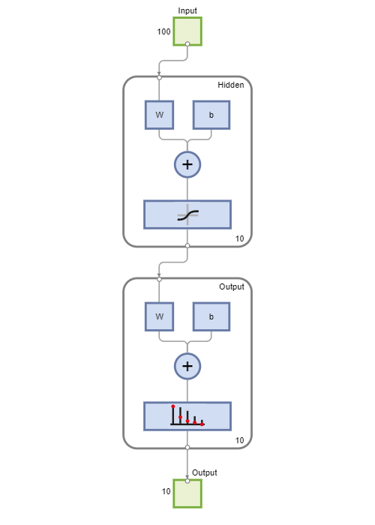

[patternnet_layer, tr] = train(patternnet_layer, features2, one_hot_labels);
view(patternnet_layer);

disp("On observe que la couche patternnet contient 2 couches, une couche cachée avec une fonction d'activation non linéaire (ici une fonction sigmoïde) et une couche de sortie avec une fonction softmax permettant d'obtenir la probabilité d'appartenance à l'une des 10 classes.")

On observe que la couche patternnet contient 2 couches, une couche cachée avec une fonction d'activation non linéaire (ici une fonction sigmoïde) et une couche de sortie avec une fonction softmax permettant d'obtenir la probabilité d'appartenance à l'une des 10 classes.



% Préparation des données de test
Xtest = dataset.dataset.test.images(1:5000, :)';
Xtest_labels = dataset.dataset.test.labels(1:5000, :);

% Encodage one-hot des labels de test
one_hot_labels_test = zeros(num_classes, size(Xtest_labels, 1));
for i = 1:size(Xtest_labels, 1)
    one_hot_labels_test(Xtest_labels(i) + 1, i) = 1;
end

% Empilement des autoencodeurs et du réseau de neurones
stacked_NN = stack(autoenc1, autoenc2, patternnet_layer);

% Prédictions sur le jeu de test
y = stacked_NN(Xtest);

% Conversion des prédictions en labels
[~, predicted_labels] = max(y, [], 1); % Trouver les indices des max
predicted_labels = predicted_labels - 1; % Ajuster pour correspondre aux indices des labels

% Affichage des prédictions et des labels réels
disp('Prédictions pour les 5 premières images :');

Prédictions pour les 5 premières images :


disp(predicted_labels(1:5));

     8     9     9     9     8



disp('Labels réels pour les 5 premières images :');

Labels réels pour les 5 premières images :


disp(Xtest_labels(1:5)');

     0     9     7     9     2



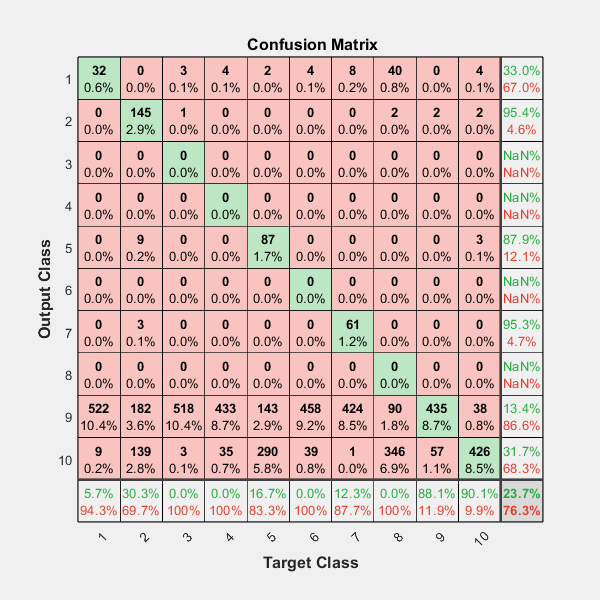


% Matrice de confusion
figure;
plotconfusion(one_hot_labels_test, y);

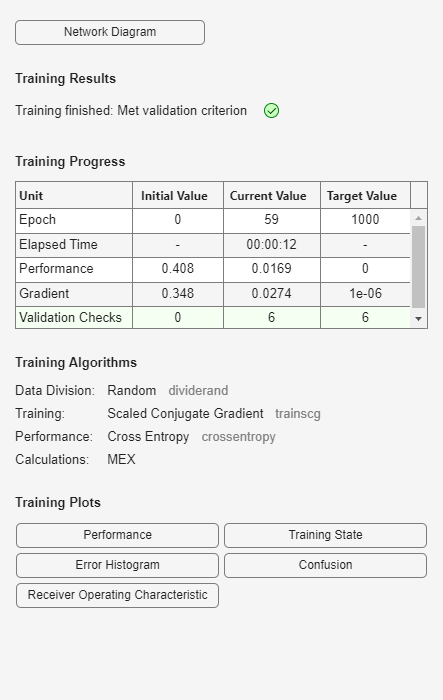


% Fine-tuning du réseau complet
stacked_NN = train(stacked_NN, Xtrain, one_hot_labels);

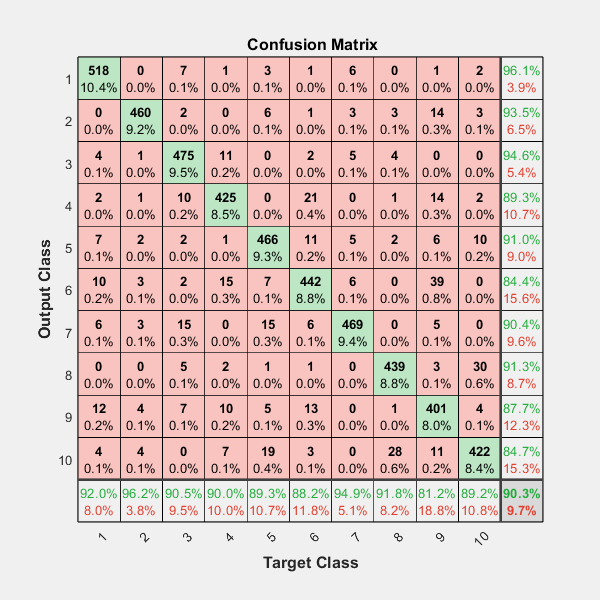


% Prédictions après fine-tuning
y_fine_tuned = stacked_NN(Xtest);
figure;
plotconfusion(one_hot_labels_test, y_fine_tuned);

On observe que les résultats des prédictions après fine-tuning augmente considérablement la qualité de prédiction du réseau.

### **5/Entraînement de la couche de classification avec softnet**

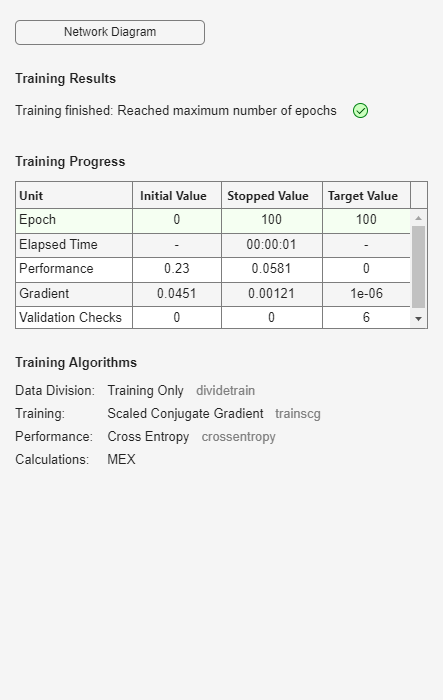

softmax_layer =

    Neural Network
 
              name: 'Softmax Classifier'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 1
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 1010
        sampleTime: 1
 
    connections:
 
       biasConnect: true
      inputCon

% Création de la couche Softmax
softmax_layer = trainSoftmaxLayer(features2,one_hot_labels,'MaxEpochs',100)

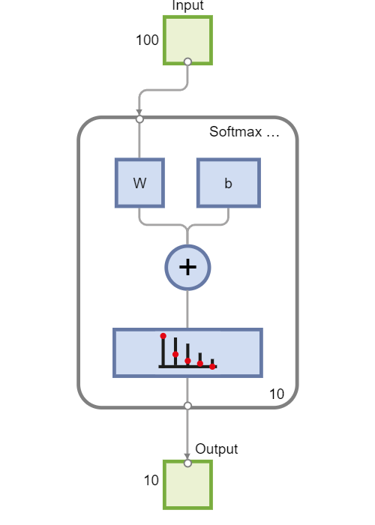


% Affichage de la structure de la couche
view(softmax_layer);


% Empilement des autoencodeurs et du réseau de neurones
stacked_NN = stack(autoenc1, autoenc2, softmax_layer);

% Prédictions sur les données de test
y_softmax = stacked_NN(Xtest); % Sorties du réseau (probabilités par classe)

% Conversion des sorties Softmax en indices de classe
[~, predicted_softmax_labels] = max(y_softmax, [], 1); % Indices des classes prédits (1 à 10)
predicted_softmax_labels = predicted_softmax_labels - 1; % Ajustement pour correspondre aux labels (0 à 9)

% Affichage des prédictions pour les 5 premières images
disp('Prédictions Softmax pour les 5 premières images :');

Prédictions Softmax pour les 5 premières images :


disp(predicted_softmax_labels(1:5));

     0     9     9     9     2



disp('Labels réels pour les 5 premières images :');

Labels réels pour les 5 premières images :


disp(Xtest_labels(1:5)');

     0     9     7     9     2



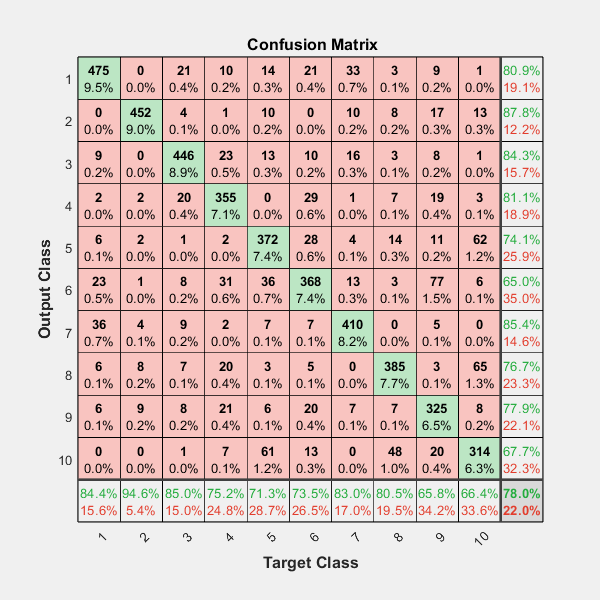


% Encodage one-hot des labels réels pour la matrice de confusion
num_classes = 10;
one_hot_labels_test = zeros(num_classes, size(Xtest_labels, 1));
for i = 1:size(Xtest_labels, 1)
    one_hot_labels_test(Xtest_labels(i) + 1, i) = 1; % Encodage au format one-hot
end

% Encodage one-hot des prédictions
one_hot_predicted = zeros(num_classes, size(predicted_softmax_labels, 2));
for i = 1:size(predicted_softmax_labels, 2)
    one_hot_predicted(predicted_softmax_labels(i) + 1, i) = 1;
end

% Affichage de la matrice de confusion
figure;
plotconfusion(one_hot_labels_test, one_hot_predicted);

### **Bilan :**

On observe que le réseau de classification utilisant `patternnet` produit de meilleures performances en termes de classification. Cela peut s'expliquer par la structure du réseau, qui inclut deux fonctions d'activation clés :

- Une fonction d'activation non linéaire de type sigmoïde (comme `tansig` ou `logsig`) appliquée dans les couches cachées, permettant au réseau de modéliser des relations complexes entre les données d'entrée.

- Une fonction Softmax dans la couche de sortie, qui convertit les scores du réseau en probabilités normalisées pour chaque classe, facilitant l'interprétation des prédictions.

Cette combinaison offre une plus grande expressivité au réseau, ce qui le rend particulièrement adapté pour des tâches de classification multi-classes. En revanche, des couches plus simples, comme une seule couche Softmax, peuvent manquer de capacité à capturer des relations non linéaires dans les données, ce qui peut expliquer de moins bonnes performances.

`patternnet`** :**

- Un réseau de neurones multicouche (MLP, Multi-Layer Perceptron) avec des couches cachées.

- Il utilise des algorithmes d'entraînement tels que *backpropagation* pour ajuster les poids.

- **Usage principal** :

- Idéal pour des tâches de classification complexe avec des relations non linéaires entre les caractéristiques et les classes.

- **Avantages** :

- Capacité à capturer des relations complexes grâce à des couches cachées.

- Plus flexible car on peut ajuster le nombre de couches et de neurones par couche.

- Peut traiter des données bruitées ou des ensembles de données plus complexes.

- **Inconvénients** :

- Peut être plus lent à entraîner pour de grands ensembles de données.

- Risque de surapprentissage si les hyperparamètres ne sont pas bien réglés.

**2. **`softnet`** :**

- Un réseau de neurones simple avec une seule couche cachée et une fonction *softmax* pour la classification.

- Il est particulièrement adapté aux tâches simples ou comme dernière couche d'un réseau plus complexe (comme un réseau convolutif, CNN).

- **Usage principal** :

- Bon choix pour des tâches de classification simples ou pour une tâche à faible complexité.

- **Avantages** :

- Rapide à entraîner, car il ne comporte qu'une seule couche.

- Utile comme dernière couche pour des architectures plus complexes.

- Évite le surapprentissage pour des ensembles de données simples ou de petite taille.

- **Inconvénients** :

- Performance limitée pour des tâches complexes, car il ne peut pas apprendre de relations non linéaires profondes.